# Current Ranger monitor

clear all
device = serialport("COM6",115200)

device =   Serialport with properties:

                 Port: "COM6"
             BaudRate: 115200
    NumBytesAvailable: 865

  Show all properties, functions



tic 
for k=1:200000
    data=readline(device);
    x(k) = str2double(data);
end
telapsed = toc;
samprate = k/toc

samprate = 2.6288e+03

device = [];

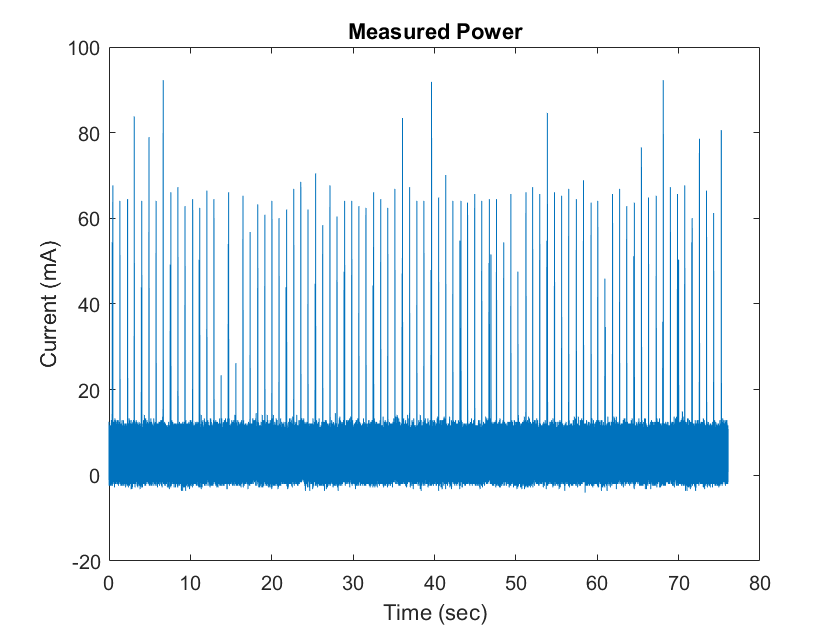

%% handle data
t = (1:length(x))/samprate;
plot(t,x*1000);
title('Measured Power')
xlabel('Time (sec)');
ylabel('Current (mA)');

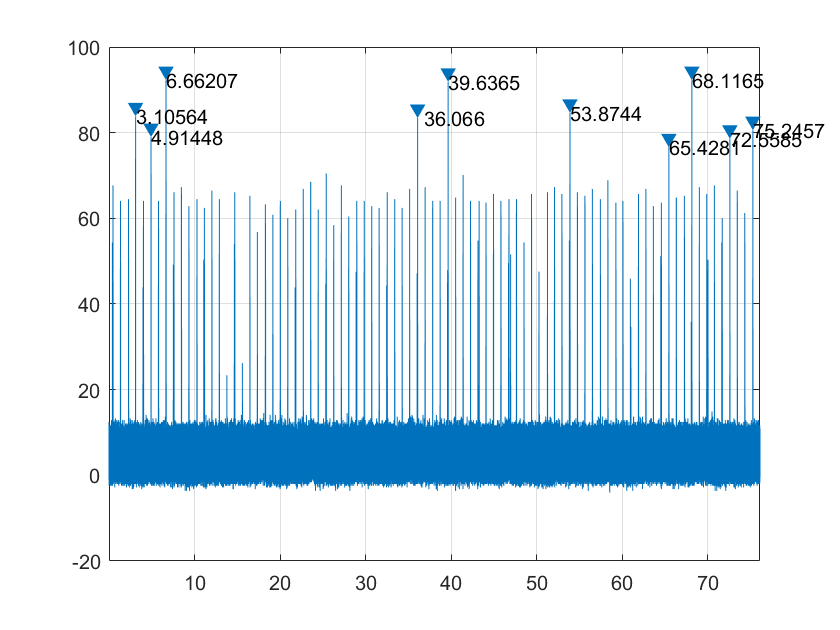


npeaks = 10;

[pks,loc]=findpeaks(x*1000,t,'NPeaks',npeaks,'MinPeakDistance',0.5,'SortStr','descend');
findpeaks(x*1000,t,'NPeaks',npeaks,'MinPeakDistance',0.5,'SortStr','descend');
text(loc+0.02,pks,num2str(loc'));

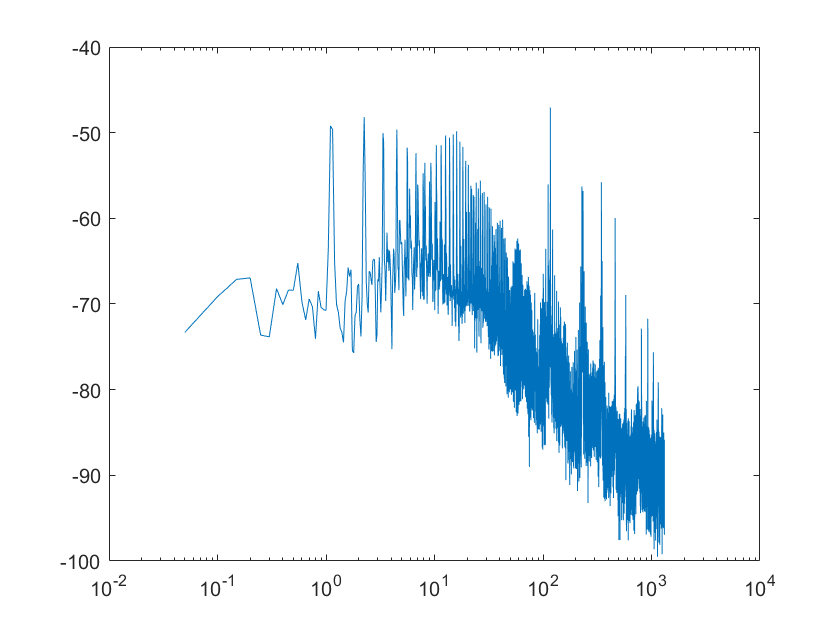

wlen = round(samprate)*20;
[Pxx,F] = pwelch(detrend(x),wlen,wlen/2,wlen,samprate);
semilogx(F,10*log10(Pxx));

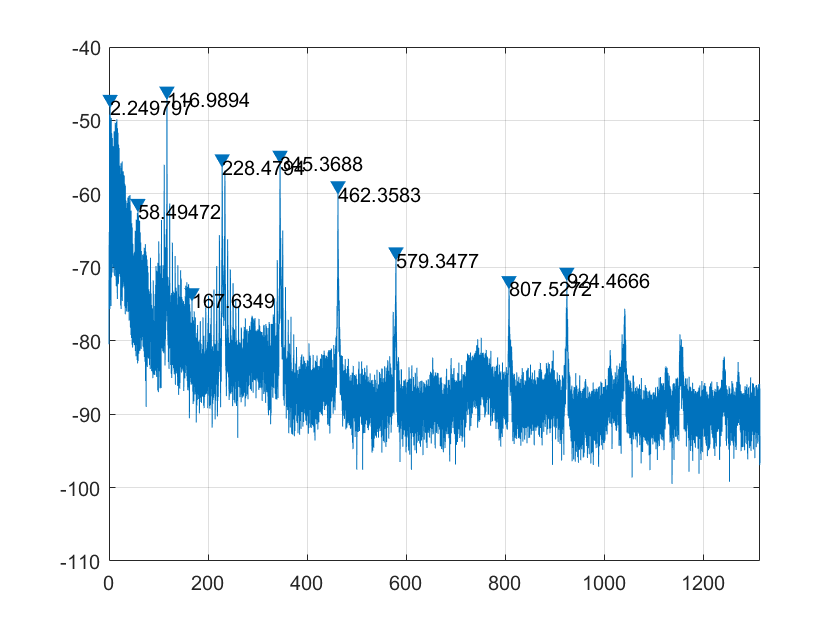

[pks,loc]=findpeaks(10*log10(Pxx),F,'NPeaks',npeaks,'MinPeakDistance',50,'SortStr','descend');
findpeaks(10*log10(Pxx),F,'NPeaks',npeaks,'MinPeakDistance',50,'SortStr','descend');
text(loc+0.02,pks,num2str(loc));